# **Image Segmentation**

## **Physical Biology of the Cell: Day 1 (July 30, 2018)**

**Get to know MATLAB :)**

**In a live script: Shortcut to switch between code and text: "option/alt" + "enter"**

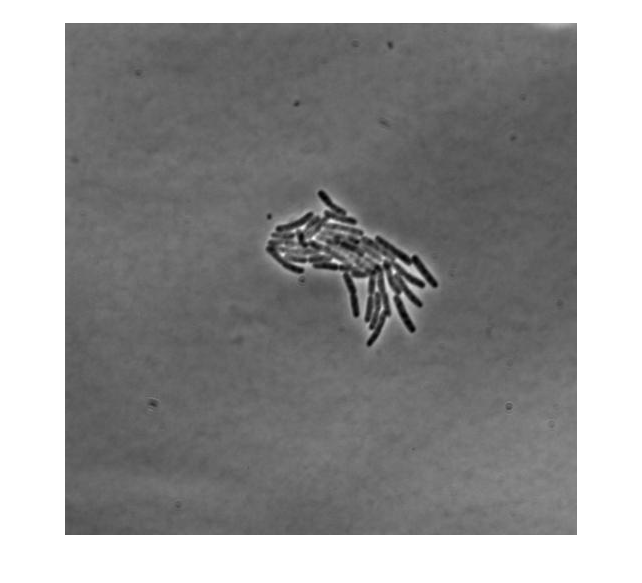

image = imread('Colony_growth_0020.jpg');
imshow(image)

Thresholding: 

min(min(image))

ans = uint8
0

max(max(image))

ans = uint8
255

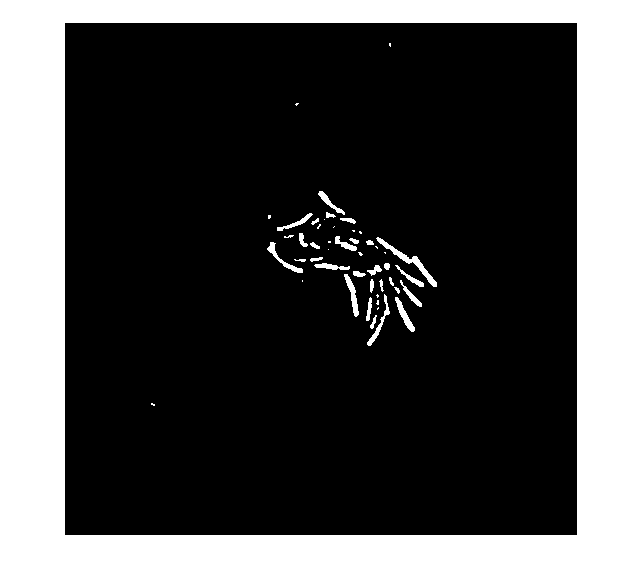

% imtool(image)

% set a threshold value
threshold = 60;
image_threshold = image < threshold;
imshow(image_threshold)

How to get area? Add up the pixels!

area = sum(sum(image_threshold))

area = 3009

The for loop

image_list = dir('*.jpg');
n_images = length(image_list);
threshold = 60;
area_list = zeros(n_images, 1);

for i = 1 : n_images
    image = imread(image_list(i).name);
    image_threshold = image < threshold;
    area = sum(sum(image_threshold));
    area_list(i) = area;
end

area_list

area_list =     72
    93
   107
   117
   133
   160
   216
   264
   264
   292


Plot things: time interval is 5 minutes. generate a plot of time vs. colony area

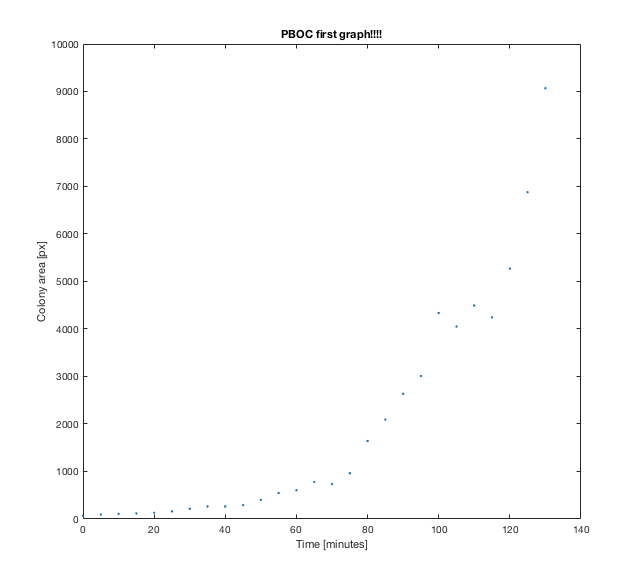

time = 0 : 5 : (length(image_list)-1)*5;
plot(time, area_list, '.')
xlabel('Time [minutes]'); ylabel('Colony area [px]')
title('PBOC first graph!!!!')